# EEE 424 - Digital Signal Processing - Coding Assignment 4 - FIR Filter

Tuna Sahin - 22201730 - EEE 424-1

1) We will use a rectangular window to design a LPF and a HPF. We will then combine these two systems by convolving their impulse responses.

% Configuration
fS = 20000;  % Sampling rate
fL = 300;    % Low cutoff frequency
fH = 3000;   % High cutoff frequency
NL = 7;      % Filter length for high-pass (must be odd)
NH = 5;      % Filter length for low-pass (must be odd)

% Low-pass filter with cutoff frequency fH
nH = 0:NH-1;
hlpf = sinc(2 * fH / fS * (nH - (NH - 1) / 2));
hlpf = hlpf / sum(hlpf);  % Normalize

% High-pass filter with cutoff frequency fL
nL = 0:NL-1;
hhpf = sinc(2 * fL / fS * (nL - (NL - 1) / 2));
hhpf = hhpf / sum(hhpf);  % Normalize
hhpf = -hhpf;
hhpf((NL + 1) / 2) = hhpf((NL + 1) / 2) + 1;  % Add impulse at center

% Convolve both filters to get band-pass filter
nom = conv(hlpf, hhpf);
nom = [nom(1:5) nom(7:11)]; %cut nom down to L=10 while keeping linear phase property
n = 0:length(nom)-1;

The transfer function coefficients ${c_i }^{\prime } s$ are given as:

disp([0:9;nom])

         0    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000
   -0.0192   -0.0520   -0.0904    0.0119    0.0872    0.0872    0.0119   -0.0904   -0.0520   -0.0192



Then the impulse response and transfer function can be written as:


$$h\left\lbrack n\right\rbrack =\sum_{i=0}^9 \delta \;\left\lbrack n-i\right\rbrack c_i$$
        
$$H\left(z\right)=\sum_{i=0}^9 z^{-i} c_i$$
 

We can then plot the zeros of our filter's transfer function. We can find the zeros by finding the roots of the polynomial whose coefficients is given by our impulse response.

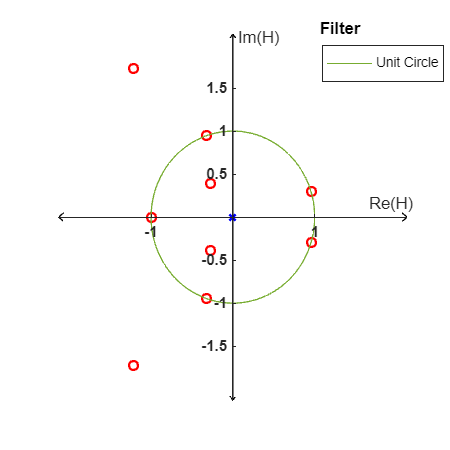

clf;
polezeroplot(zeros([1 9]),roots(nom),'Filter','H','on',[400 400]);
h = gobjects(3, 1);
h(1) = plot(cos(linspace(0,2*pi,100)),sin(linspace(0,2*pi,100)),'color',[0.4660 0.6740 0.1880],'DisplayName', 'Unit Circle'); %unit circle
legend(h([1])); %add the legend
hold off
legend("Position", [0.7171 0.8192 0.2675, 0.0812])

We can calculate the DTFT as:

omega = linspace(0,2*pi,100000);
finalsum = zeros(1,length(omega));
for i = 1:length(nom)
    finalsum = finalsum + (nom(i)*exp(1j*omega).^(-1*i));
end

Let's plot the impulse response, frequency response and the fft of our signal alltogeter as:

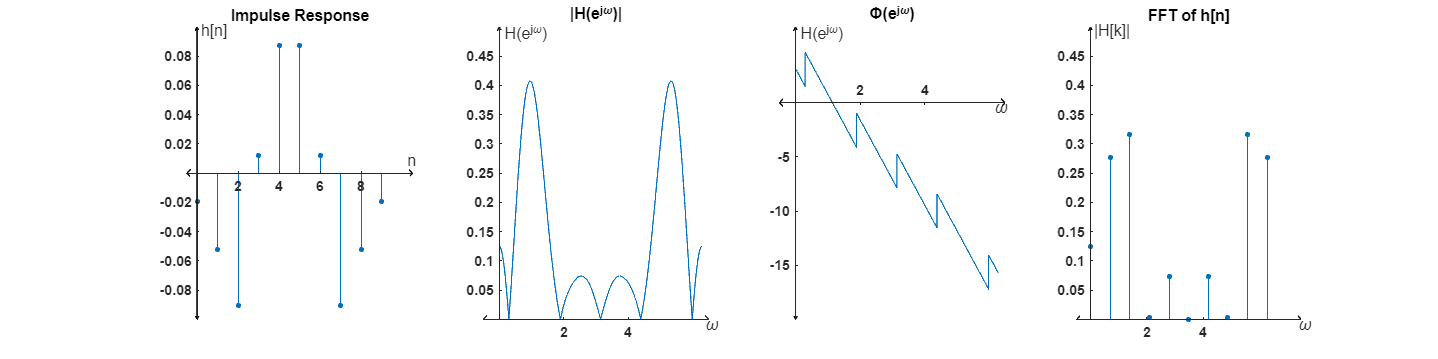

clf;
subplot(1,4,1) % impulse response
finestem(n,real(nom),'Impulse Response','n','h[n]',[-0.5 10.5],[-0.1 0.1],'off',[1600 400],'resp','o');
subplot(1,4,2) % magnitutes of FT
fineplot(omega,abs(finalsum),'|H(e^{j\omega})|','\omega','H(e^{j\omega})',[-0.5 6.5],[0 0.5],'off',[1600 400],'mag','-');
subplot(1,4,3) % phases of FT
fineplot(omega,unwrap(angle(finalsum)),'\Phi(e^{j\omega})','\omega','H(e^{j\omega})',[-0.5 6.5], [-20 7],'off',[1600 400],'phase','-');
subplot(1,4,4) % FFT of impulse response
finestem(linspace(0,2*pi,length(nom)),[abs(fft(nom))],'FFT of h[n]','\omega','|H[k]|', [-0.5 7.5],[0 0.5],'off',[1600 400],'fft','o');

We obtained a filter that has a passband between $0\ldotp 03\pi -0\ldotp 3\pi \ldotp$ If we try to improve this filter, we will have to make a trade-off between different specifications such as stopband rejection, transition band witdh etc. Therefore, while it may be possible to optimise these trade-offs, it would not be possible to design an objectively better filter.

2) In the second question, we first open our recording and reduce it to a single channel recording.

clf;
recording = audioread('recording.mp3');
monoAudio = mean(recording, 2);
monoAudio = monoAudio(1:480000); %clip 10 seconds of samples

We then need to downsample our 48kHz sampling rate recording down to 20kHz. We first upsample with 5, then apply a lowpass filter to avoid aliasing, then downsample with 12.

upsampled = zeros([1,4800000]);%upsampling
for i = 0:length(monoAudio)-1
    upsampled(i*5+1:i*5+5) = [monoAudio(i+1) zeros([1,4])];
end

inter_filtered = lowpass(upsampled,10000,240000); %prevent aliasing when downsampling

downsampled = inter_filtered(1:12:end);

Now we just have to pass our input through our system:

filtered = conv(nom,downsampled);
filtered = filtered / max(abs(filtered));

We can then listen to our filtered recording and export it.

player = audioplayer(filtered,20000);
playblocking(player);
audiowrite('filtered_recording.wav',filtered,20000)